clear
close all
hold off


En este código se va a implementar el método de Quasi-Newton para dos dimensiones. A continuación se determinan las condiciones iniciales y las constantes.

N=6; %Número de robots
iteration=500; %Número de iteraciones
step_size=0.1;
D=1; %Radio de la formación
S=10^-4*[100,1,1;1,10,0;1,0,10]; %Matriz
c0=[20;30;20]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación
w0=1; %Movimiento circular de un radián por segundo
k=1.1; %Valor para el line search inexacto
H_0=eye(3); %Hessiano inicial para la iteración

c1=10^-4;
c2=0.9; %Parámetros para el line search (c2=0.7 da solución rápida, valores más bajos resultan en un tiempo de computación notable)

colors=["ob","ok","or","oy"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
plot3(c0(1,1),c0(2,1),c0(3,1),'ob')
hold on
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
i=1;
I=eye(3);

A continuación se pasa al cálculo de la posición de los centros. Se hace uso de un método de line-search inexacto con las condiciones Strong Wolfe.

while mod_rc>0.001

    if i==iteration
        break
    end
    grad_centr(:,i)=gradient_point_3D(c(:,i),t(i),N,D,S,w0);
    alpha1=1; 
    p(:,i)=-H_0*grad_centr(:,i); %Dirección descendente
    steplengthParam=[c1,c2,alpha1,k];
    [alpha(i),u(i)]=alpha_strongWolfe3D(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0);        
    c(:,i+1)=c(:,i)-alpha(i)*H_0*grad_centr(:,i);
    grad_centr(:,i+1)=gradient_point_3D(c(:,i+1),t(i+1),N,D,S,w0);
    x_k1=c(:,i+1);
    x_k=c(:,i);
    s_k=x_k1-x_k;
    q_k=grad_centr(:,i+1)-grad_centr(:,i);
    B_k=(I-(s_k*q_k'/(q_k'*s_k)))*H_0*(I-(q_k*s_k'/(q_k'*s_k)))+s_k*s_k'/(q_k'*s_k); %Hessiano invertido
    H_0=B_k       

    c0=c(:,i);
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
    i=i+1;
end

H_0 =   294.2050   57.4728   38.3343
   57.4728   11.8297    7.2247
   38.3343    7.2247    5.8197


H_0 =     1.3887    0.2912    0.1904
    0.2912    0.8661   -0.0895
    0.1904   -0.0895    0.9402


H_0 =     1.5341   -2.5398   -1.6890
   -2.5398   41.4264   26.8468
   -1.6890   26.8468   18.8287


H_0 =     1.3243    0.2530    0.1655
    0.2530    4.2524    2.1625
    0.1655    2.1625    2.4378


H_0 =     1.3312    0.2090    0.1373
    0.2090    3.9301    1.9359
    0.1373    1.9359    2.2790


H_0 =     1.0630   -0.6652   -0.4622
   -0.6652    4.3452    2.3459
   -0.4622    2.3459    2.6511


H_0 =     0.5038   -0.0234   -0.0753
   -0.0234    4.0169    2.0712
   -0.0753    2.0712    2.4536


H_0 =     0.5039   -0.0381   -0.0798
   -0.0381    4.4531    1.3500
   -0.0798    1.3500    1.7795


H_0 =     0.5040   -0.0428   -0.0431
   -0.0428    4.7003   -0.3584
   -0.0431   -0.3584    4.6225


H_0 =     0.5039   -0.0391   -0.0454
   -0.0391    4.5231   -0.2451
   -0.0454   -0.2451    4.9072


H_0 =     0.5041   -0.0483   -0.0521
   -0.0483    4.9462    0.0517
   -0.0521    0.0517    4.9804


H_0 =     0.5041   -0.0495   -0.0517
   -0.0495    4.9986    0.0330
   -0.0517    0.0330    4.9486


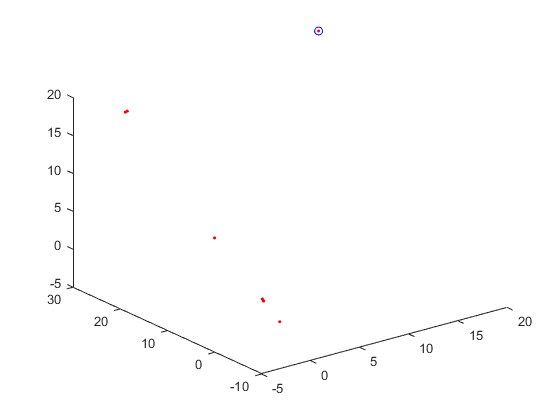

%Representación del centro
plot3(c(1,:),c(2,:),c(3,:),'.r')

hold off

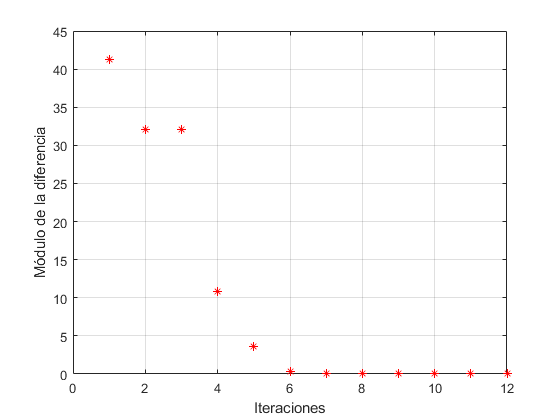

plot(1:length(mod_r_c),mod_r_c,"*r")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 1.5157e-04

c0

c0 = 	1.0e+-3 *

   -0.0030
    0.1362
    0.0664


u

u =     52     1    28     1     1     1     1     1     1     1     1     1


num_iteraciones=sum(u) %número de iteraciones

num_iteraciones = 90

Cuanto más cerca del máximo, más cuesta calcular el alpha idóneo, ya que se hace muy pequeño.